# Homework 8 (Solution) 

Math 3607

Tae Eun Kim

clear, close all, format short 

## Problem 1 (FNC 5.1.3)

One may directly type in the given coordinates. In real applications, such information may be stored in data files, *e.g.,*

and

If these files are saved in the same directory as your main live script, you can import the data using `load` function

load('shape_top.dat')
load('shape_bottom.dat')

The data files are now loaded and  are stored as `shape_top` and `shape_bottom:`

shape_top

shape_top =          0         0
    0.5100    0.1600
    0.9600    0.1600
    1.0600    0.4300
    1.2900    0.6200
    1.5500    0.4800
    1.7300    0.1900
    2.1300    0.1800
    2.6100         0


shape_bottom

shape_bottom =          0         0
    0.5800   -0.1600
    1.0400   -0.1500
    1.2500   -0.3000
    1.5600   -0.2900
    1.7600   -0.1200
    2.1900   -0.1200
    2.6100         0


### Version 1.

With the data-loading tip out of the way, let's go ahead and plot the saucer. 

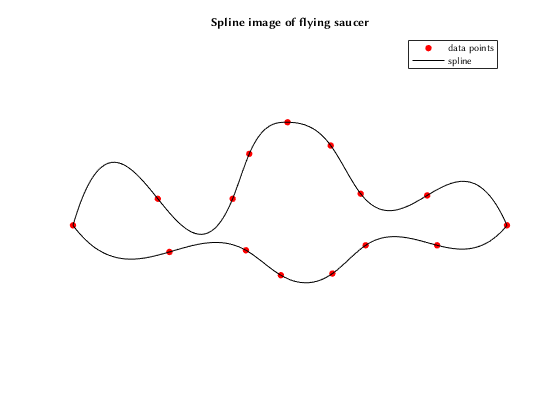

% top
xdp_t = shape_top(:,1);
ydp_t = shape_top(:,2);
x_t = linspace(xdp_t(1), xdp_t(end), 200)';
y_t = interp1(xdp_t, ydp_t, x_t, 'spline');

% bottom
xdp_b = shape_bottom(:,1);
ydp_b = shape_bottom(:,2);
x_b = linspace(xdp_b(1), xdp_b(end), 200)';
y_b = interp1(xdp_b, ydp_b, x_b, 'spline');

% plot
clf
plot([xdp_t; xdp_b], [ydp_t; ydp_b], 'r.', 'MarkerSize', 20), hold on
plot([x_t; flip(x_b)], [y_t; flip(y_b)], 'k')
axis equal, axis off
title('Spline image of flying saucer')
legend('data points', 'spline')

### Version 2.

A cleaner version using a for-loop a new type of MATLAB array called *cells*:

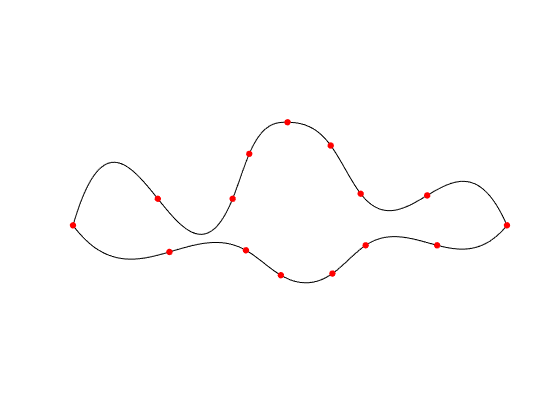

DATA{1} = shape_top;         % DATA is a cell array.
DATA{2} = shape_bottom;
clf
for i = 1:2
    xdp = DATA{i}(:,1);
    ydp = DATA{i}(:,2);
    x = linspace(xdp(1), xdp(end), 200)';
    y = interp1(xdp, ydp, x, 'spline');
    plot(x, y, 'k'), hold on
    plot(xdp, ydp, 'r.', 'MarkerSize', 20)
    hold on
end
axis equal, axis off

If you learn more about cell arrays and structures, read Section 6.3.

## Problem 2 (FNC 5.1.4)

Note that the function $q(x)$ is a quadratic polynomial:

$q(x) = \frac{a}{2} x(x-1) - b(x-1)(x+1) + \frac{c}{2} x (x+1)$.

### (a)

- $q(-1) = \frac{a}{2} (-1)(-2) - b(-2)(0) + \frac{c}{2} (-1) (0) = a$.

- $q(0)  = \frac{a}{2} (0)(-1) - b(-1)(1) + \frac{c}{2} (0)(1) = b$.

- $q(1)  = \frac{a}{2} (1)(0) - b(0)(2) + \frac{c}{2} (1) (2) = c$.

### (b)

Let $X(z) = \frac{z-x_0}{h}$.  Then

- $X( x_0 ) = 0$,

- $X(x_0 \pm h) = \pm 1$.

This provides a suitable change of variables: define $p$ by


$$p(z) = q(X(z)) = \frac{a}{2} \frac{z-x_0}{h} \frac{ z - x_0 - h}{h} - b \frac{z-x_0-h}{h} \frac{z-x_0+h}{h} + \frac{c}{2} \frac{z-x_0}{h} \frac{z-x_0+h}{h}$$


which simplifies to

$p(z) = \frac{1}{h^2} \left[ \frac{a}{2} (z-x_0) (z-x_0-h) - b (z-x_0 -h) (z-x_0 +h) + \frac{c}{2} (z-x_0)(z-x_0+h) \right]$.

This is clearly a quadratic polynomial (as a composition of linear and quadratic polynomial). Furthermore, it interpolates all three points $(x_0-h, a)$, $(x_0,b)$, and $(x_0+h,c)$ by construction. For instance,

$p(x_0-h) = q(X(x_0-h)) = q(-1) = a$,

where the first equality follows from the definition $p(z) = q(X(z))$, the second due to the noted property of the map $X(z)$, and the last from the fact that $q$ interpolates $(-1, a)$. 

## Problem 3 (FNC 5.3.5)

A slight modification of the example in the live script accompanying Lecture 25 would do. For the sake of comparison, cardinal piecewise linear interpolants, a.k.a. hat functions, are also plotted.

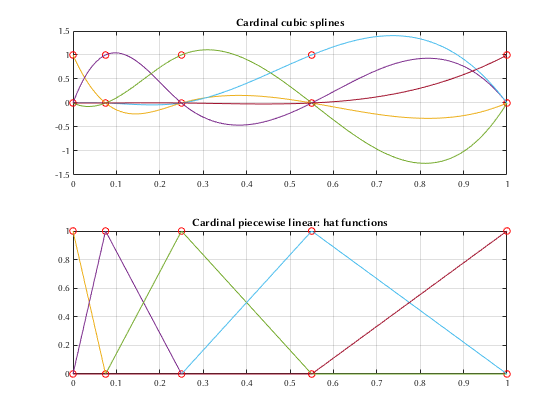

xdp = [0 0.075 0.25 0.55 1]';  % t is the nodes (x data points)
I = eye(length(xdp));          % identity matrix for easy access to cardinal data (y)
x = linspace(0, 1, 400)';
clf
subplot(2,1,1)
plot(xdp, zeros(size(xdp)), 'ro'), hold on
plot(xdp, ones(size(xdp)), 'ro')
for j = 1:length(xdp)
    plot(x, interp1(xdp, I(:,j), x, 'spline'))
end
grid on
title('Cardinal cubic splines')

subplot(2,1,2)
plot(xdp, zeros(size(xdp)), 'ro'), hold on
plot(xdp, ones(size(xdp)), 'ro')
for j = 1:length(xdp)
    plot(x, interp1(xdp, I(:,j), x))
end
grid on
title('Cardinal piecewise linear: hat functions')

## Problem 4 (FNC 5.3.6)

Denote by $Q(x)$ the quadratic spline that interpolates $(x_i, y_i)$, for $i = 1, \ldots, n$, such that

$Q(x) = q_i(x) = c_{i,1} + c_{i,2}(x-x_i) + c_{i,3}(x-x_i)^2$ on $I_i$ for $i = 1, \ldots, n-1$

where $I_i = [x_i, x_{i+1})$ if $i = 1, \ldots, n-2$ and $I_{n-1} = [x_{n-1}, x_n]$. So there are $3(n-1) = 3n-3$ coefficients to be determined. 

The function $Q$ must interpolate the given data:

$Q(x_i) = y_i$ for $i = 1, \ldots, n$                 [ $n$ equations ]

Since $Q$ must be $C^1[x_1, x_n]$, $Q$ and $Q'$ must be continuous at all interior breakpoints:

$q_{i-1}(x_i) = q_i(x_i)$ for $i = 2,\ldots, n-1$         [ $n-1$ equations ]

$q_{i-1}'(x_i) = q_i'(x_i)$ for $i = 2, \ldots, n-1$         [ $n-1$ equations ]

All together, there are $3n -2$ equations, that is, one condition short of the $3n-3$ conditions required. (Just in the case of cubic splines, there are various ways to impose this additional condition, *e.g.*, $Q'(x_1) = 0$ or $Q''(x_0) = 0$. 

## Problem 5 (LM 12.2--15; 2-D cubic splines)

*Disclaimer*: The solution below utiltizes parametrization by the arclength variable, not the pseudo-arclength variable. This is just to illustrate another way of solving the same problem. For a solution using the proper parametrization, please see p.1569 of LM or my tutorial video. (Any submission using arclength will not receive full credits since the problem specifically asked to use pseudo-arclength variable.)

### (a)

Without loss of any generality, we will work with the unit circle $x^2 + y^2 = 1$, which can be parametrized by the arclength variable $s$ as

$\langle x(s), y(s) \rangle = \langle \cos(s), \sin(s) \rangle$, $s \in [0, 2\pi]$. 

(Note that the parametrization by $s$ is equivalent to the usual parametrization by $\theta$ because along the unit circle the length of the arc spanned by angle $\theta$ is equals $\theta$.)

Thus we view $x$ and $y$ as separate variables dependent on the common variable $s$. Consequently, the data points on the unit circle must now be arranged into two data sets as

$(s_j, x_j) = (s_j, \cos(s_j))$ and $(s_j, y_j) = (s_j, \sin(s_j))$ for $j = 1, \ldots, n$

where $0 = s_1 < s_2 < \cdots < s_n = 2\pi$.  

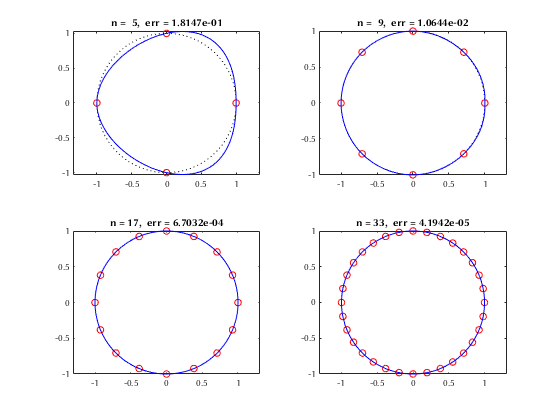

nvals = [5 9 17 33];
clf
for j = 1:length(nvals)
    n = nvals(j);
    sdp = linspace(0, 2*pi, n)';    % nodes: arc length
    xdp = cos(sdp);                 % ordinates: x-coord.
    ydp = sin(sdp);                 % ordinates: y-coord.
    
    s = linspace(0, 2*pi, 1000)';   % query points
    xcirc = cos(s);                 % x-coord. on circle
    ycirc = sin(s);                 % y-coord. on circle
    x = interp1(sdp, xdp, s, 'spline');
    y = interp1(sdp, ydp, s, 'spline');
    
    err = max( sqrt((x-xcirc).^2 + (y-ycirc).^2) );
    
    subplot(2,2,j)
    plot(xdp, ydp, 'ro'), hold on   % plot data points
    plot(xcirc, ycirc, 'k:')        % plot circle
    plot(x, y, 'b')                 % plot spline
    axis equal
    title(sprintf('n = %2d,  err = %8.4e', n, err))
end

### (a,i)

Though we were able to work out the previous part with `interp1`, we do need to use `spline` for this part to incorporate the first-derivative boundary conditions. The basic syntax of `spline` is very similar to that of `interp1`:

If the first derivatve values at the end points shall be specified (this is called the *clamped cubic spline*), prepend and append the values to the vector of ordinates, in our case, `xdp `and `ydp`. So when MATLAB recognizes that the second input to `spline `has exactly two more elements than the first input, then it uses the interior elements as data points while the first and the last elements as derivative values at the end points. As we will see below, this results in an improved interpolation as can be confirmed both numerically and graphically. 

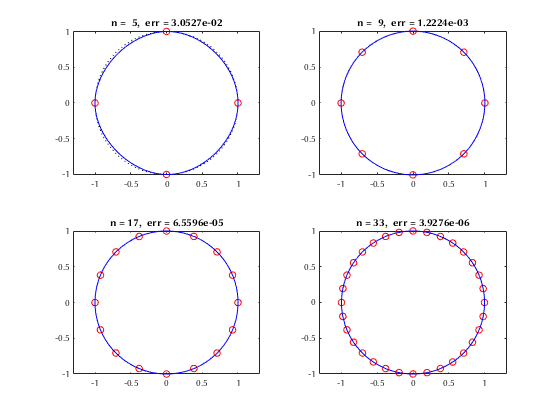

clf
for j = 1:length(nvals)
    n = nvals(j);
    sdp = linspace(0, 2*pi, n)';    % nodes: arc length
    xdp = [0; cos(sdp); 0];         % ordinates: x-coord.
    ydp = [1; sin(sdp); 1];         % ordinates: y-coord.
    
    s = linspace(0, 2*pi, 1000)';   % query points
    xcirc = cos(s);                 % x-coord. on circle
    ycirc = sin(s);                 % y-coord. on circle
    x = spline(sdp, xdp, s);
    y = spline(sdp, ydp, s);
    
    err = max( sqrt((x-xcirc).^2 + (y-ycirc).^2) );
    
    subplot(2,2,j)
    plot(xdp(2:end-1), ydp(2:end-1), 'ro'), hold on   % plot data points
    plot(xcirc, ycirc, 'k:')        % plot circle
    plot(x, y, 'b')                 % plot spline
    axis equal
    title(sprintf('n = %2d,  err = %8.4e', n, err))
end

### (b)

In this part, I will only show the clamped spline as in (a,i).

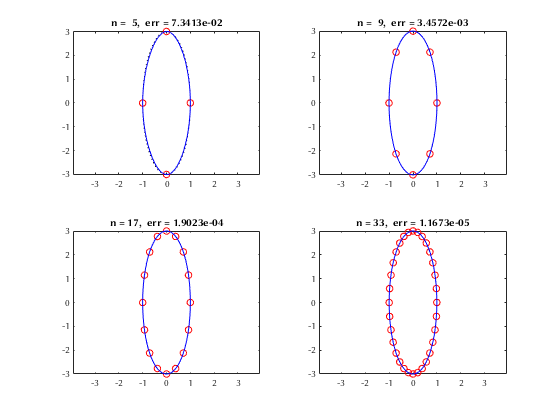

clf
for j = 1:length(nvals)
    n = nvals(j);
    tdp = linspace(0, 2*pi, n)';    % nodes: arc length
    xdp = [0; cos(tdp); 0];         % ordinates: x-coord.
    ydp = [3; 3*sin(tdp); 3];       % ordinates: y-coord.
    
    t = linspace(0, 2*pi, 1000)';   % query points
    xell = cos(t);                  % x-coord. on ellipse
    yell = 3*sin(t);                % y-coord. on ellipse
    x = spline(tdp, xdp, t);
    y = spline(tdp, ydp, t);
    
    err = max( sqrt((x-xell).^2 + (y-yell).^2) );
    
    subplot(2,2,j)
    plot(xdp(2:end-1), ydp(2:end-1), 'ro'), hold on   % plot data points
    plot(xell, yell, 'k:')        % plot ellipse
    plot(x, y, 'b')                 % plot spline
    axis equal
    title(sprintf('n = %2d,  err = %8.4e', n, err))
end